# 一阶倒立摆

## 参数设置

clear;clc;
%参数
% syms x t F f M m I g l b;
M = 0.5;
m = 0.3;
l = 0.3;
I = 1/3*m*l^2;
g = 9.8;
b = 0.1;

## 状态矩阵


$$\dot{x}=Ax+Bu\\
y=Cx+Du$$



$$x=
\left[
\matrix{
x  & \dot{x}  & \theta  & \dot{\theta }}
\right]
$$


a=(M+m)*I+M*m*l^2;
A=[0 1 0 0;
    0 -b*(I+m*l^2)/a m^2*l^2*g/a 0;
    0 0 0 1;
    0 -b*m*l/a (M+m)*m*g*l/a 0];
B=[0 ;
   (I+m*l^2)/a;
   0;
   m*l/a];
C=[1 0 0 0;
    0 0 1 0];
D=[0 ;
    0];

## MPC


$$x(k+1)=Ax(k)+bu(k)$$


n = size(A,1);
p = size(B,2);
T = 0.01;       %控制周期
I1 = eye(n);
A_ = I1 + T*A;  %离散化预测模型参数A
B_ = T*B;       %离散化预测模型参数B

Q=eye(n);       %状态误差权重
R=0.01*eye(p);  %控制输出权重

k_steps=100;    %仿真时间，存储所有仿真结果
X_K = zeros(n,k_steps); %状态序列
X_K(:,1) = [0 ;0 ;0; 0];%初始状态
U_K = zeros(p,k_steps); %输入序列

N=5;%控制时域
r_k=[10 ;0 ;0 ;0];%参考状态
R_K=zeros(n*N,1);
for i = 0:N-1
    R_K(i*n+1:n*i+n,:)=[r_k];
end


for k = 1 : k_steps
    [E,H]=MPC_Matrices(A_,B_,Q,R,R_K,X_K,N,k);
    U_K(:,k) = Prediction(X_K(:,k),E,H,N,p);
    X_K(:,k+1) = A_*X_K(:,k)+B_*U_K(:,k);
end


找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>

找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在

subplot(2, 1, 1);

hold;

已锁定最新绘图



for i =1 :size (X_K,1)

plot (X_K(i,:));

end

legend("x1","x2","x3","x4")

hold off;

subplot (2, 1, 2);

hold;

已锁定最新绘图


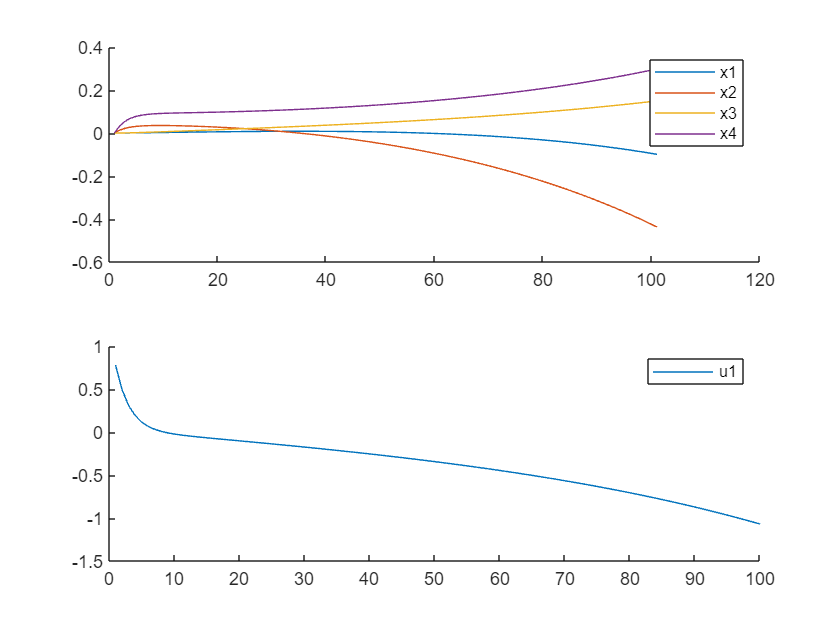


for i =1 : size (U_K,1)

plot (U_K(i,:));

end

legend("u1")

function [E,H]=MPC_Matrices(A,B,Q,R,R_K,X_K,N,k)
    n = size(A,1);
    p = size(B,2);

    M = zeros(N*n,n);
    C = zeros(n*N,p*N);
    tmp = eye(n);

    i = 0;
    rows = (1:n);
    C(rows,:) = [tmp*B,C(1:n,1:p*(N-1))];
    tmp = A*tmp;
    M(rows,:) = tmp;

    for i = 1 : N-1
        rows = i*n + (1:n);
        C(rows,:) = [tmp*B,C(rows-n,1:end-p)];
        tmp = A*tmp;
        M(rows,:) = tmp;
    end

    Q_ = kron(eye(N),Q);
    R_ = kron(eye(N),R);

    E = M*X_K(:,k)-R_K(:,1);
    E = E'*Q_*C;
    H = C'*Q_*C + R_;
end

function u_k=Prediction(x_k,E,H,N,p)
    U_K = zeros(N*p,1);
    U_K = quadprog(H*2,E*2);%最优化函数，得到使代价函数最小的状态量
    u_k = U_K(1:p,1);%取第一个值预测值
end